## **Function to draw a signal in time domain**

## Main Code

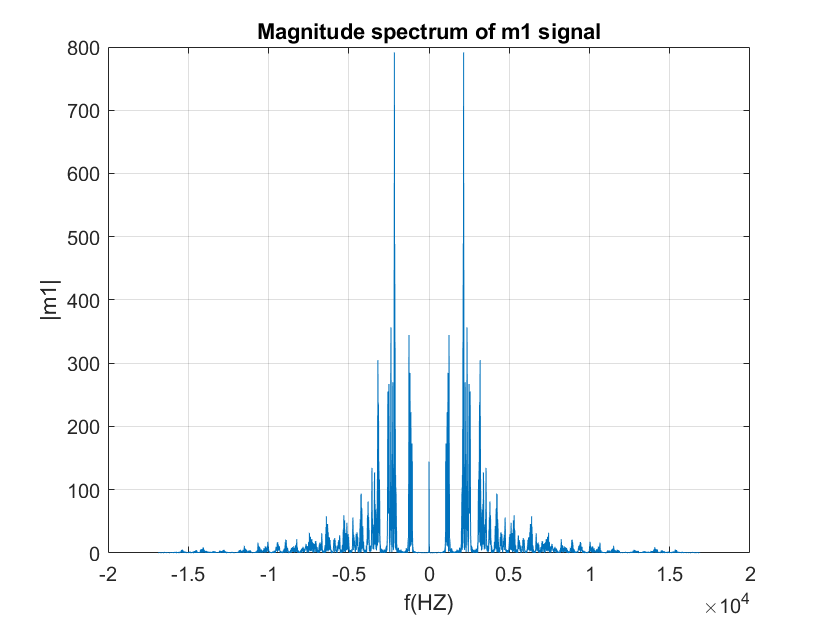

[message1,samplingFrequency1]=audioread("time.wav");
[message2,samplingFrequency2]=audioread("intro.wav");
[message3,samplingFrequency3]=audioread("Cheers.wav");
maxSamples = max(max(length(message2), length(message3)), length(message1));
if length(message1) ~= maxSamples
    message1 = padarray(message1, maxSamples - length(message1), 0, "post");
end
if length(message2) ~= maxSamples
    message2 = padarray(message2, maxSamples - length(message2), 0, "post");
end
if length(message3) ~= maxSamples
    message3 = padarray(message3, maxSamples - length(message3), 0, "post");
end
upSampleingRate = 30;
s_mags = abs(fftshift(fft(message1)));
num_bins = length(s_mags);
plot(- num_bins / 2: num_bins / 2 - 1, s_mags),grid on;
title('Magnitude spectrum of m1 signal');
xlabel('f(HZ)');
ylabel('|m1|');

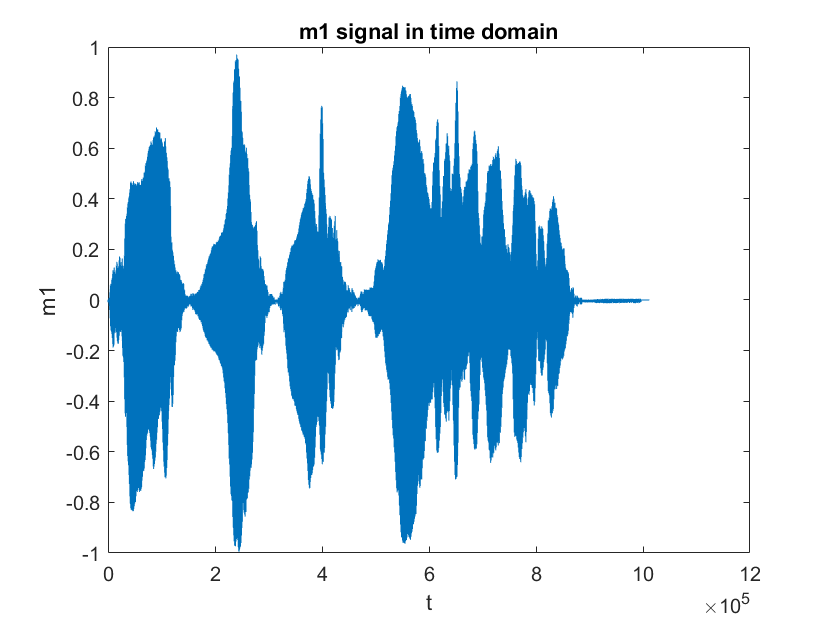

message1 = resample(message1, upSampleingRate, 1);
message2 = resample(message2, upSampleingRate, 1);
message3 = resample(message3, upSampleingRate, 1);
% message1 = lowpass(message1,500, samplingFrequency1);
% message2 = lowpass(message2,500, samplingFrequency2);
% message3 = lowpass(message3,500, samplingFrequency3);
figure(1)
plot(message1);
title("m1 signal in time domain")
ylabel("m1")
xlabel("t")

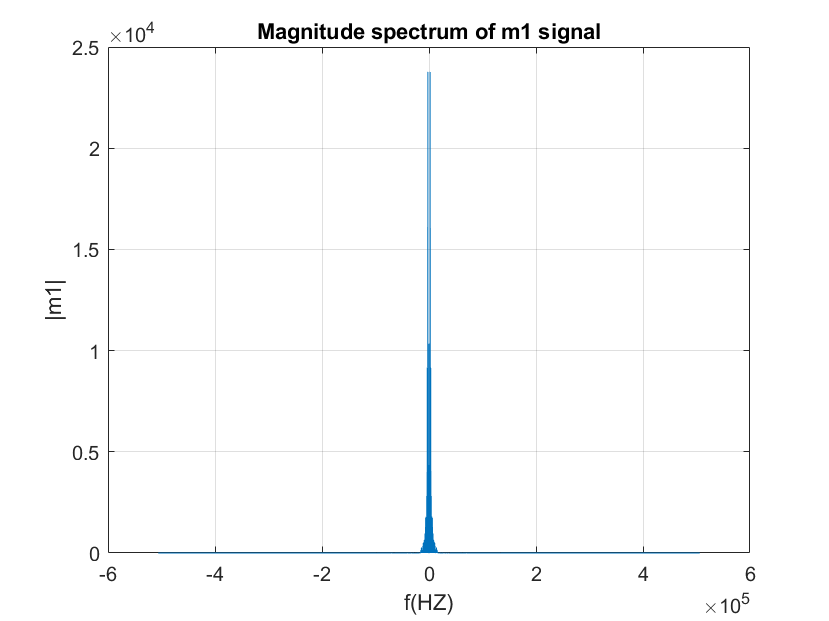



s_mags = abs(fftshift(fft(message1)));
num_bins = length(s_mags);
plot(- num_bins / 2: num_bins / 2 - 1, s_mags),grid on;
title('Magnitude spectrum of m1 signal');
xlabel('f(HZ)');
ylabel('|m1|');



% figure(2)
% plot(message2);
% title("m2 signal in time domain")
% ylabel("m2")
% xlabel("t")
% 
% 
% s_mags = abs(fftshift(fft(message2)));
% num_bins = length(s_mags);
% plot([- num_bins / 2: num_bins / 2 - 1], s_mags),grid on;
% title('Magnitude spectrum of m2 signal');
% xlabel('f(HZ)');
% ylabel('|m2|');
% 
% 
% 
% figure(3)
% plot(message3);
% title("m3 signal in time domain")
% ylabel("m3")
% xlabel("t")
% 
% 
% s_mags = abs(fftshift(fft(message3)));
% num_bins = length(s_mags);
% plot([- num_bins / 2: num_bins / 2 - 1], s_mags),grid on;
% title('Magnitude spectrum of m3 signal');
% xlabel('f(HZ)');
% ylabel('|m3|');


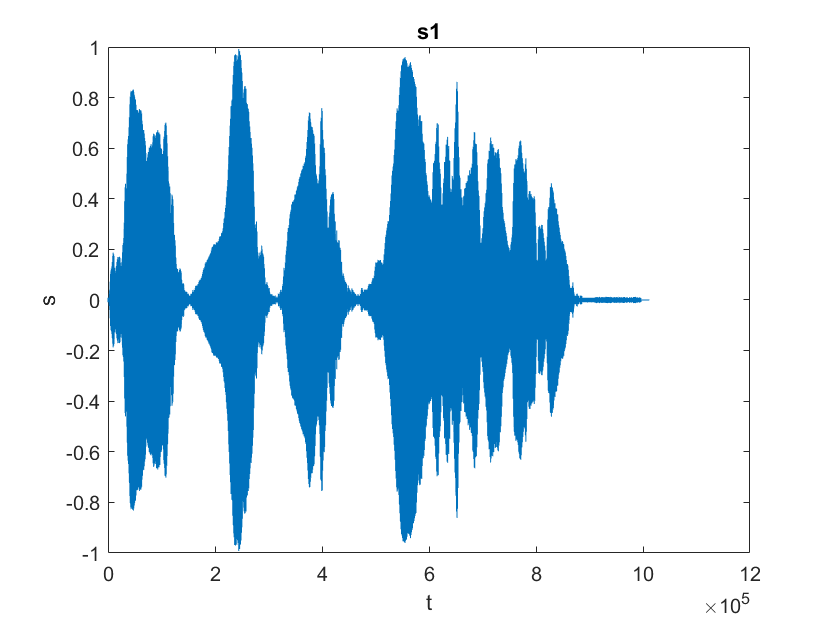

fcarrier1 = 115000;
fcarrier2 = 60000;
duration = length(message1)./(samplingFrequency1 * upSampleingRate);
m = samplingFrequency1 * upSampleingRate;
t2=-(duration-1/m) / 2:1/m:(duration-1/m) / 2 ;
carrier1 = cos(2 * pi * fcarrier1 * t2);
s1 = message1' .* carrier1;


%duration = length(message2)./(samplingFrequency2 * upSampleingRate);
%t2=0:1/(samplingFrequency2 * upSampleingRate):duration-1/(samplingFrequency2 * upSampleingRate);
carrier2 = cos(2 * pi * fcarrier2 * t2);
s2 = message2' .* carrier2;


%duration = length(message3)./(samplingFrequency3 * upSampleingRate);
%t2=0:1/(samplingFrequency3 * upSampleingRate):duration-1/(samplingFrequency3 * upSampleingRate);
carrier3 = sin(2 * pi * fcarrier2 * t2);
s3 = message3' .* carrier3;

%s2 = modulate(message2, fcarrier2, samplingFrequency2, "qam",message3);
s = s1 + s2 + s3;


figure(3)
plot(s1);
title("s1")
ylabel("s")
xlabel("t")

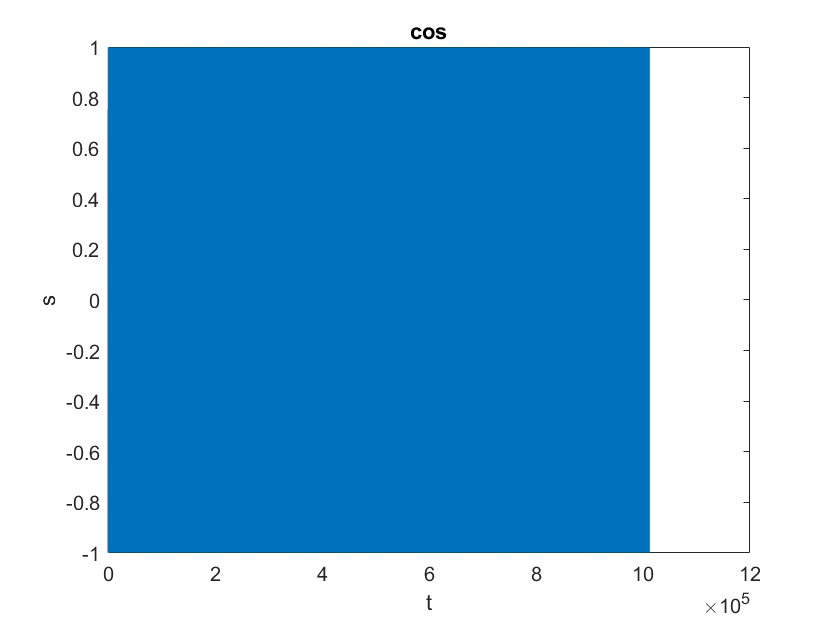



figure(4)
plot(carrier1);
title("cos")
ylabel("s")
xlabel("t")

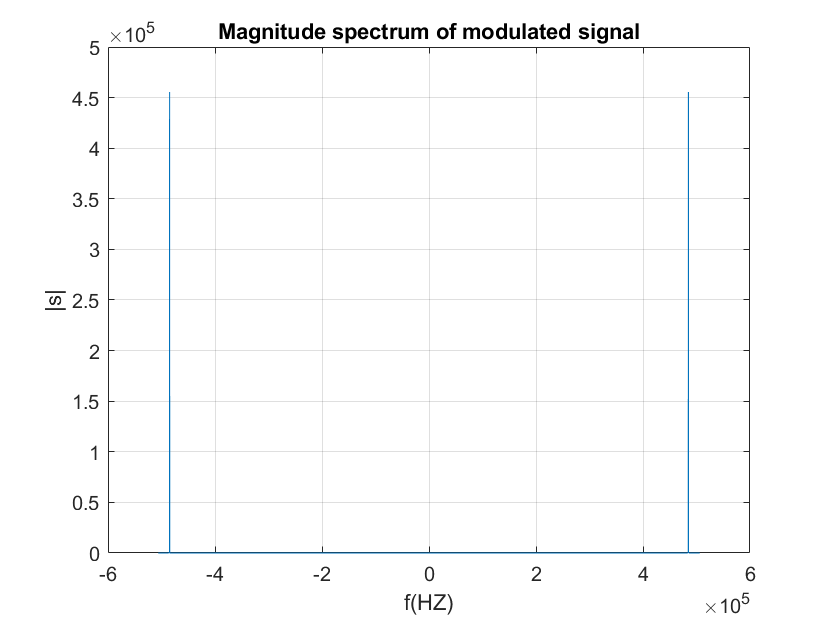



f = (length(carrier1))/2*linspace(-1,1,(length(carrier1)));

s_mags = abs(fftshift(fft(carrier1)));
% num_bins = length(s_mags);
plot(f, s_mags),grid on;
title('Magnitude spectrum of modulated signal');
xlabel('f(HZ)');
ylabel('|s|');


% s_mags = abs(fftshift(fft(s1)));
% num_bins = length(s_mags);
% plot([- num_bins / 2: num_bins / 2 - 1], s_mags),grid on;
% title('Magnitude spectrum of modulated signal');
% xlabel('f(HZ)');
% ylabel('|s|');

output1 = 2*(carrier1 .* s)

output1 =    -0.0088    0.0084   -0.0116   -0.0394   -0.0194    0.0117   -0.0116   -0.0469   -0.0225    0.0160   -0.0041   -0.0366   -0.0152    0.0156    0.0026   -0.0145   -0.0037    0.0026   -0.0012    0.0076    0.0042   -0.0225   -0.0162    0.0219    0.0065   -0.0482   -0.0323    0.0279    0.0063   -0.0600   -0.0376    0.0282    0.0069   -0.0512   -0.0285    0.0232    0.0071   -0.0277   -0.0118    0.0114    0.0031   -0.0026    0.0011   -0.0080   -0.0069    0.0132    0.0039   -0.0301   -0.0195    0.0182


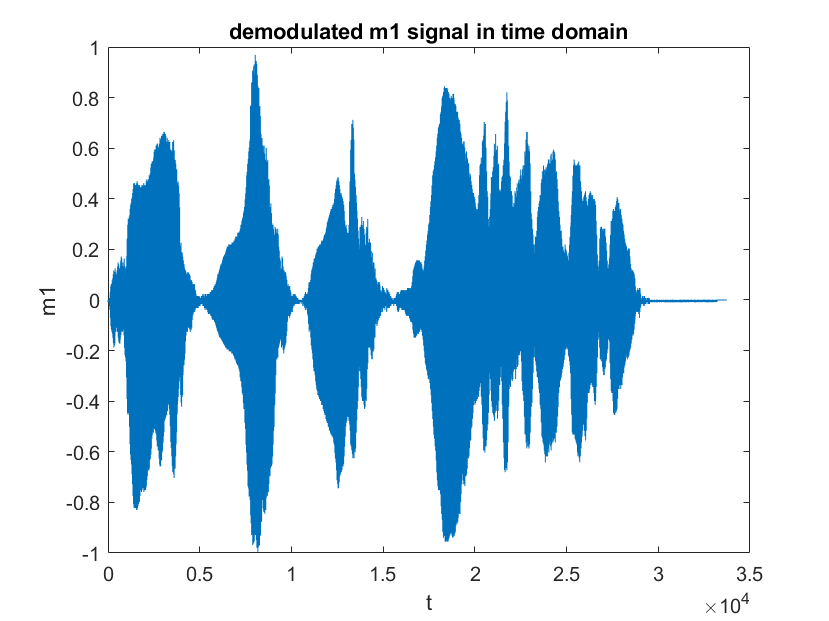

% output1 = bandpass(s, [100000 140000 ] , samplingFrequency1 * upSampleingRate) .* carrier1;

output2 = 2*(carrier2 .* s);

output3 = 2*(carrier3 .* s);



output1 = resample(output1, 1,upSampleingRate);
output2 = resample(output2, 1,upSampleingRate);
output3 = resample(output3, 1,upSampleingRate);
% output2 = downsample(output2, upSampleingRate);
% output3 = downsample(output3, upSampleingRate);
% output1 = lowpass(output1,samplingFrequency1/2, samplingFrequency1);
% message2 = lowpass(message2,500, samplingFrequency2);
% message3 = lowpass(message3,500, samplingFrequency3);


audiowrite('time3.wav', output1, samplingFrequency1)
audiowrite('time4.wav', output2, samplingFrequency2)
audiowrite('time5.wav', output3, samplingFrequency3)
% [output2, output3] = demod(s,fcarrier2,samplingFrequency1,"qam");

figure(1)
plot(output1);
title("demodulated m1 signal in time domain")
ylabel("m1")
xlabel("t")

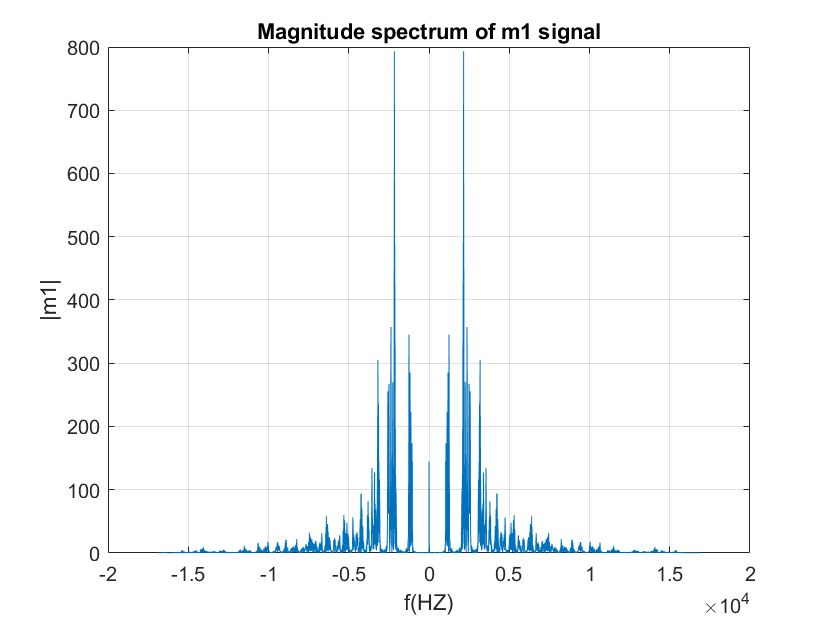



s_mags = abs(fftshift(fft(output1)));
num_bins = length(s_mags);
plot(- num_bins / 2: num_bins / 2 - 1, s_mags),grid on;
title('Magnitude spectrum of m1 signal');
xlabel('f(HZ)');
ylabel('|m1|');



% figure(2)
% plot(output2);
% title("demodulated m2 signal in time domain")
% ylabel("m2")
% xlabel("t")
% 
% 
% s_mags = abs(fftshift(fft(output2)));
% num_bins = length(s_mags);
% plot([- num_bins / 2: num_bins / 2 - 1], s_mags),grid on;
% title('Magnitude spectrum of m2 signal');
% xlabel('f(HZ)');
% ylabel('|m2|');
% 
% 
% 
% figure(3)
% plot(output3);
% title("demodulated m3 signal in time domain")
% ylabel("m3")
% xlabel("t")
% 
% 
% s_mags = abs(fftshift(fft(output3)));
% num_bins = length(s_mags);
% plot([- num_bins / 2: num_bins / 2 - 1], s_mags),grid on;
% title('Magnitude spectrum of m3 signal');
% xlabel('f(HZ)');
% ylabel('|m3|');


